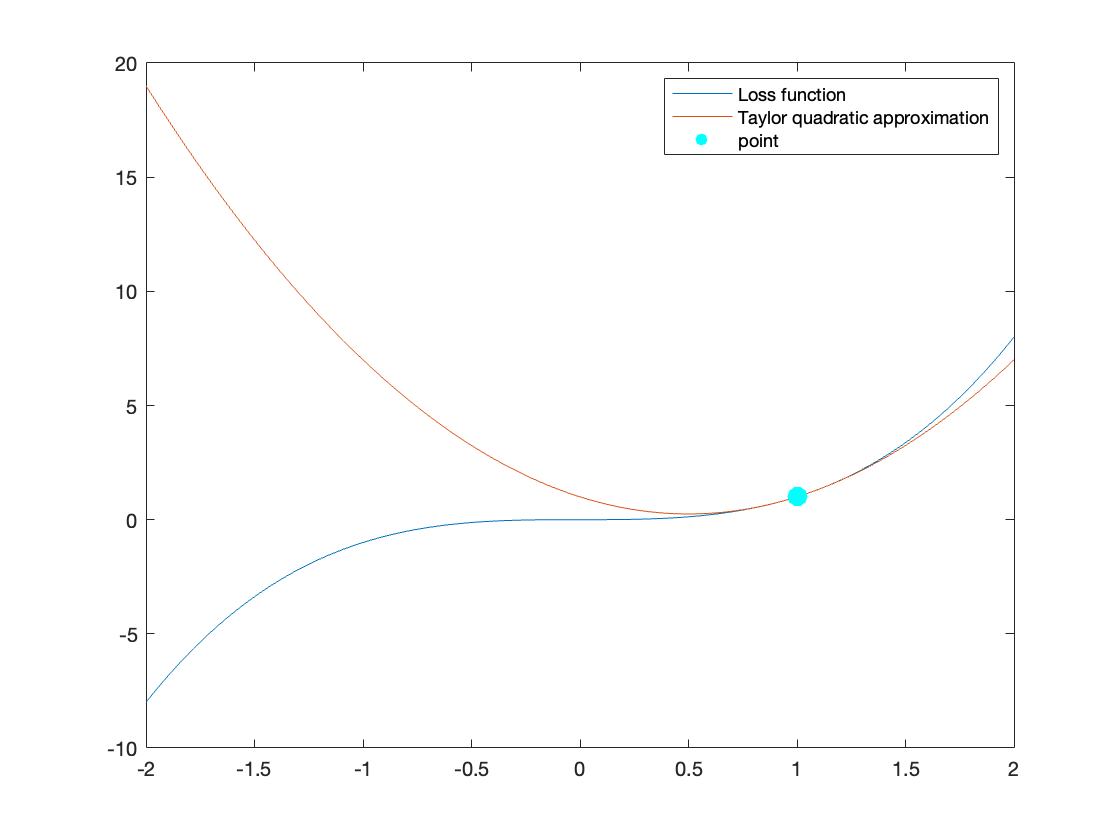

x_range = -2:1e-2:2;

% loss function
f = @(x) x.^3;
% graident point
x0 = 1;
% graident function
g = @(x) 3*x.^2;
% hessian function
h = @(x) 6.*x;
% quadractic approximation function
f1 = @(delta) f(x0) + (delta-x0).*g(x0) + 1/2.*(delta-x0).*h(x0).*(delta-x0);

% plot
plot(x_range,f(x_range),x_range,f1(x_range))
hold on
scatter(x0, f(x0), 100, 'filled', "MarkerFaceColor",'c')
legend('Loss function','Taylor quadratic approximation', 'point')
hold off